## **Driver test program to check Clothoids library**

**Test Intersection**

close all;

x0     = 0;
y0     = 0;
theta0 = pi*0.7;
k0     = -0.1;
dk     = 0.05;
L      = 50;
C1     = ClothoidCurve( x0, y0, theta0, k0, dk, L );

x0     = -10;
y0     = -1;
theta0 = pi/4;
k0     = 0.1;
dk     = -0.049;
L      = 50;
C2     = ClothoidCurve( x0, y0, theta0, k0, dk, L );

[PA1,PA2,PA3] = C1.bbTriangles();
[PB1,PB2,PB3] = C2.bbTriangles();

max_angle = pi/2;
max_size  = 0.5;

npts = 1000;

C1.plot(npts,'Color','red','LineWidth',3);
hold on;
C2.plot(npts,'Color','black','LineWidth',3);

C1.plotTBox(PA1,PA2,PA3,'Color','black','LineWidth',1);
C2.plotTBox(PB1,PB2,PB3,'Color','blue','LineWidth',1);

size(PA1)

ans =      2   340


size(PB1)

ans =      2   333



%[s1,s2] = intersectClothoid( C1, C2 );
tic
[s1,s2] = C1.intersect( C2 );
[s1,s2] = C1.intersect( C2 );
[s1,s2] = C1.intersect( C2 );
[s1,s2] = C1.intersect( C2 );
[s1,s2] = C1.intersect( C2 );
[s1,s2] = C1.intersect( C2 );
[s1,s2] = C1.intersect( C2 );
[s1,s2] = C1.intersect( C2 );
[s1,s2] = C1.intersect( C2 );
[s1,s2] = C1.intersect( C2 );
toc

Elapsed time is 1.536565 seconds.


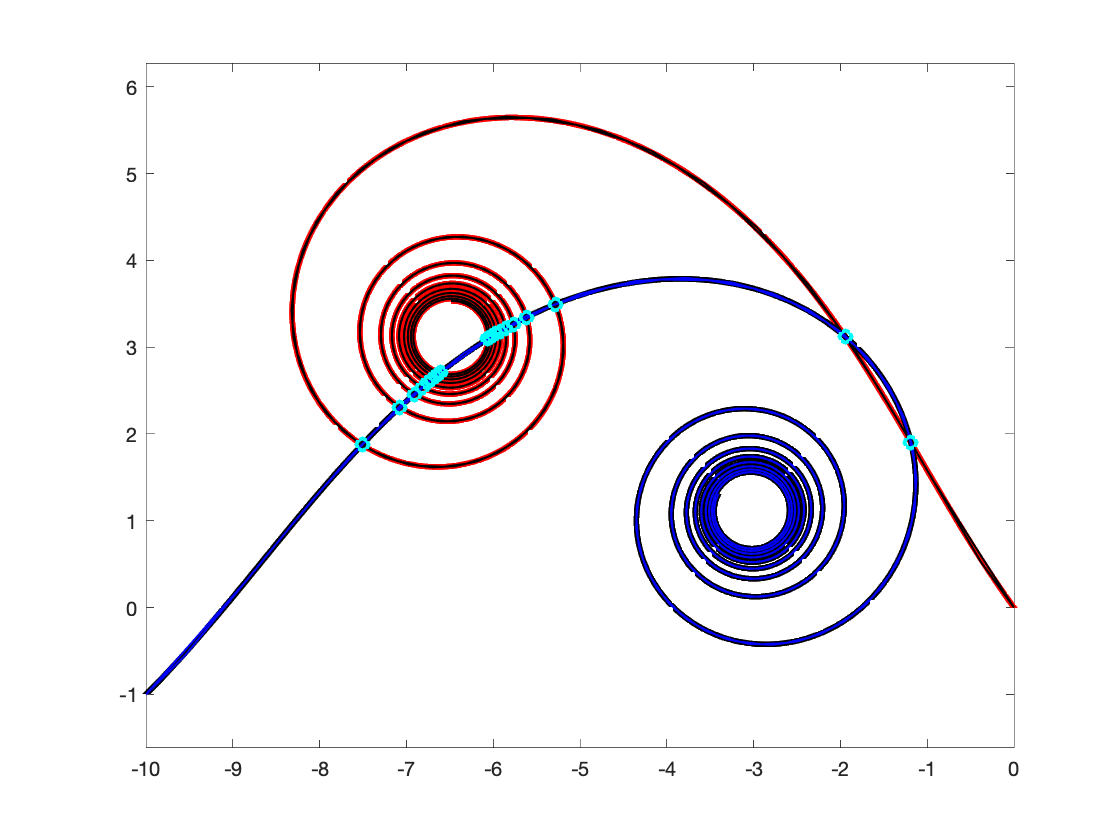


XY1 = C1.eval( s1 );
XY2 = C2.eval( s2 );

plot( XY1(1,:), XY1(2,:), 'ob', 'LineWidth', 2 );
plot( XY2(1,:), XY2(2,:), 'oc', 'LineWidth', 2 );

axis equal;